(a)

theta0 = 1;
thetad0 = 0;
g = 9.81;
omega2 = 9;
R = g/omega2;
gamma = 0.5;

[t,w] = pendulum_damp(R,theta0,thetad0,gamma);
ind1 = find(w(:,2).*circshift(w(:,2), [-1 0]) <= 0);
period1 = 2*mean(diff(t(ind1(1:length(ind1)-1))));
omega1 = 2*pi/period1

omega1 = 2.9710

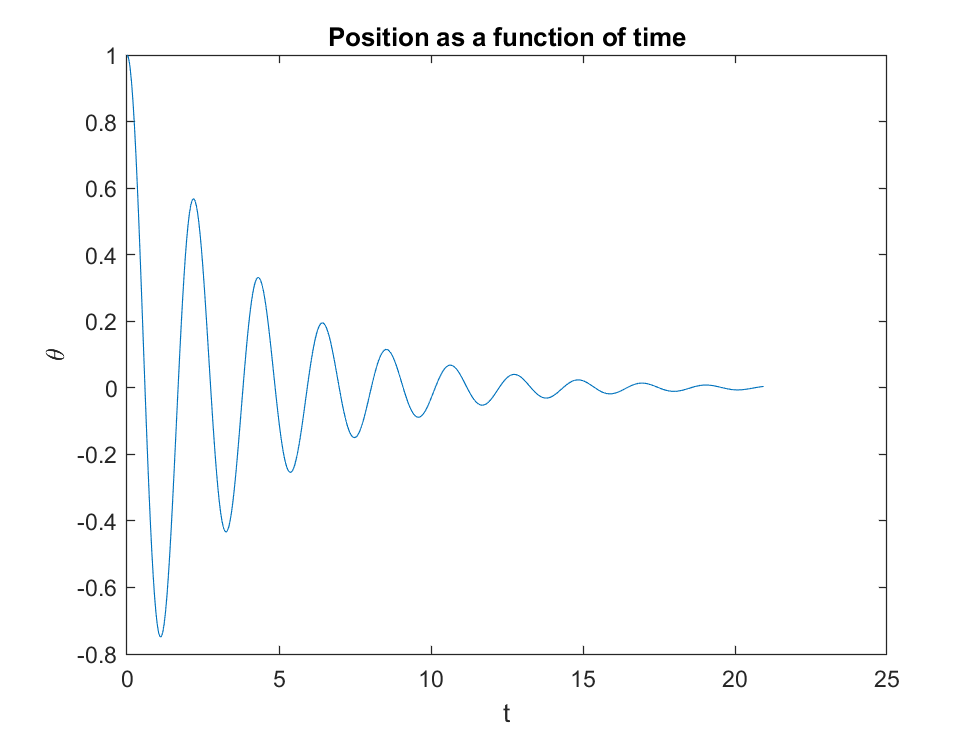

figure
plot(t, w(:,1))
xlabel('t')
ylabel('\theta')
title('Position as a function of time')

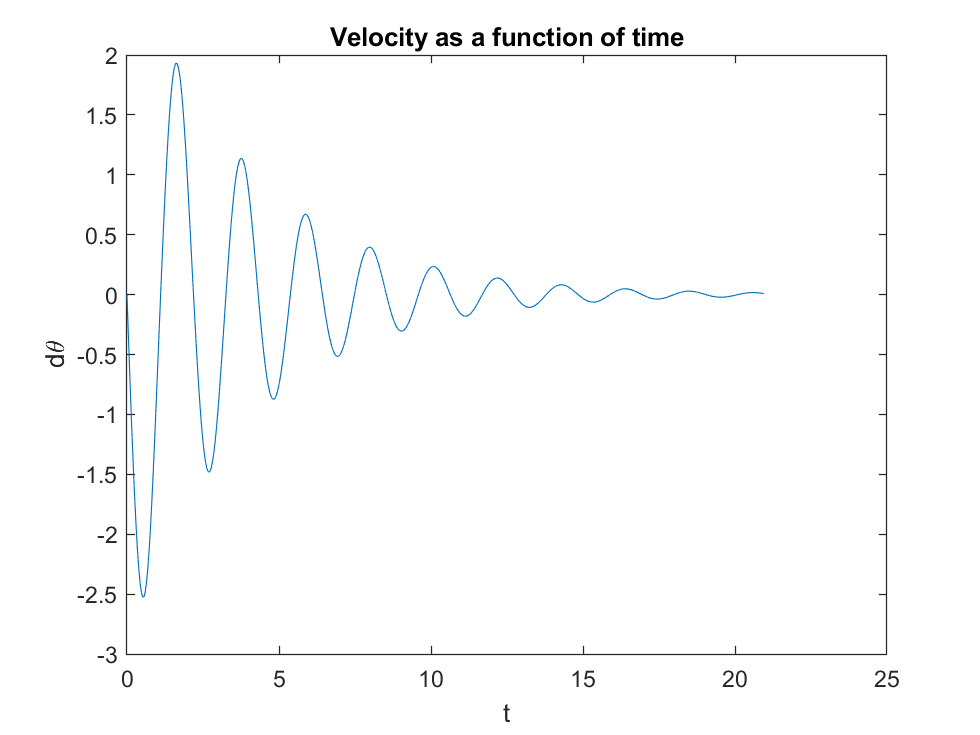

figure
plot(t, w(:,2))
xlabel('t')
ylabel('d\theta')
title('Velocity as a function of time')

(b) damped period (2.11) becomes shorter then undamped (2.23) maybe because the distance it travels decreases. the omega becomes bigger (2.97 vs 2.88).

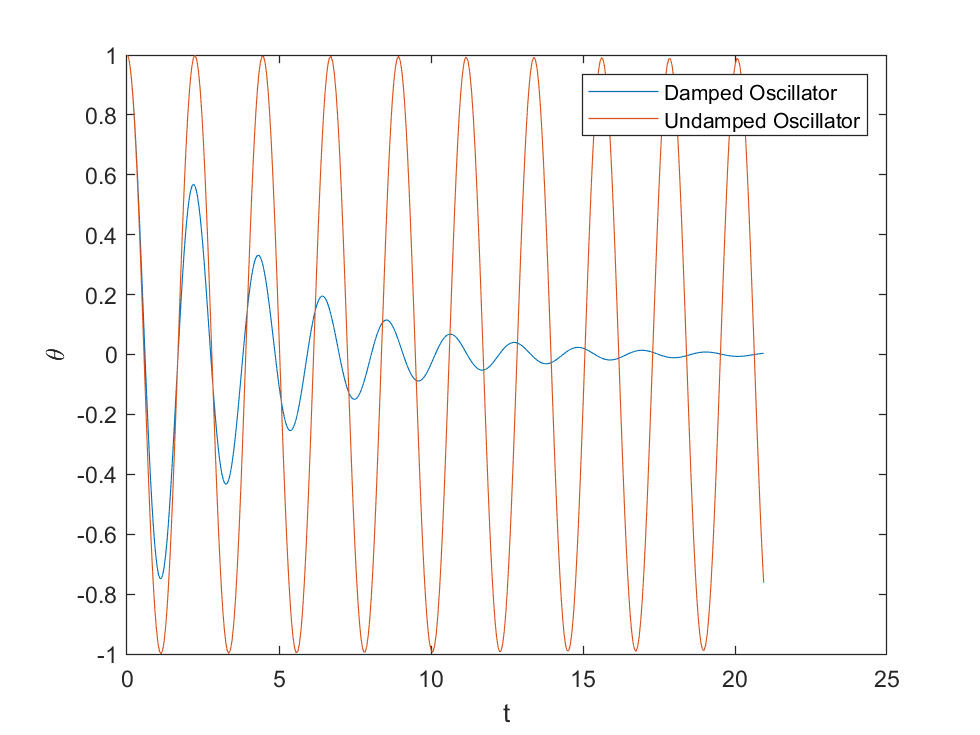

[t1,w1] = pendulum_sin(R,theta0,thetad0);
ind2= find(w1(:,2).*circshift(w1(:,2), [-1 0]) <= 0);
period2 = 2*mean(diff(t1(ind2(1:end-1))));
omega2 = 2*pi/period2;
figure
plot(t,w(:,1), t1,w1(:,1))
xlabel('t')
ylabel('\theta')
legend('Damped Oscillator','Undamped Oscillator')

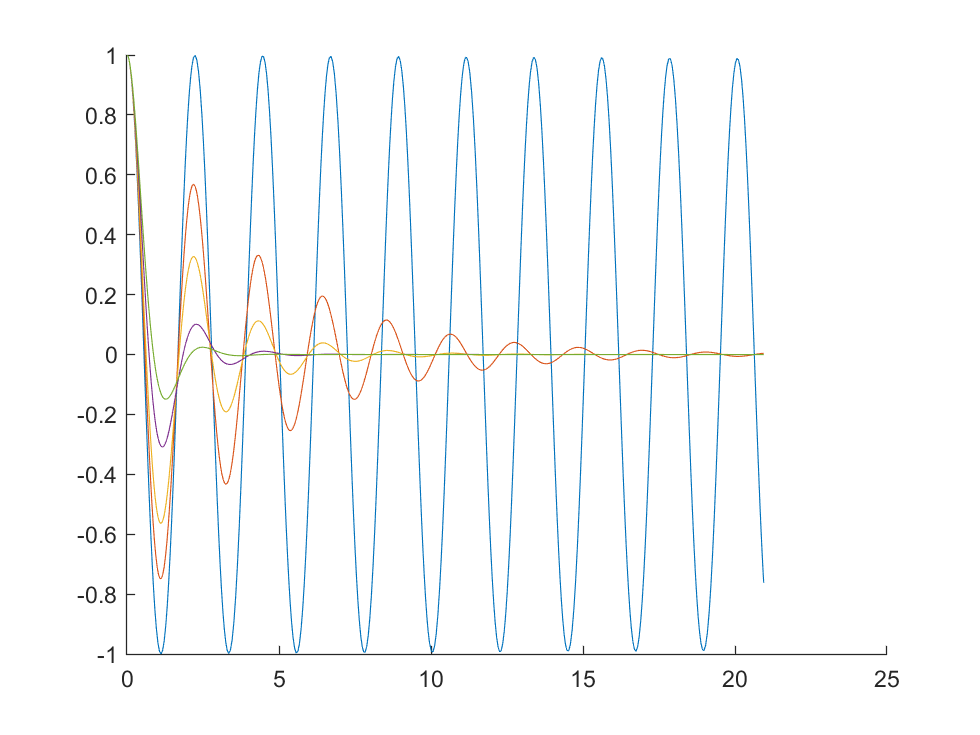

figure
hold on
g_list = [0 0.5 1 2 3];
w_list = [];
for gamma=[0 0.5 1 2 3]
    [t,w] = pendulum_damp(R,theta0,thetad0,gamma);
    ind = find(w(:,2).*circshift(w(:,2), [-1 0]) <= 0);
    period = 2*mean(diff(t(ind(1:end-1))));
    w_list = [w_list, 2*pi/period];
    plot(t,w(:,1))
end

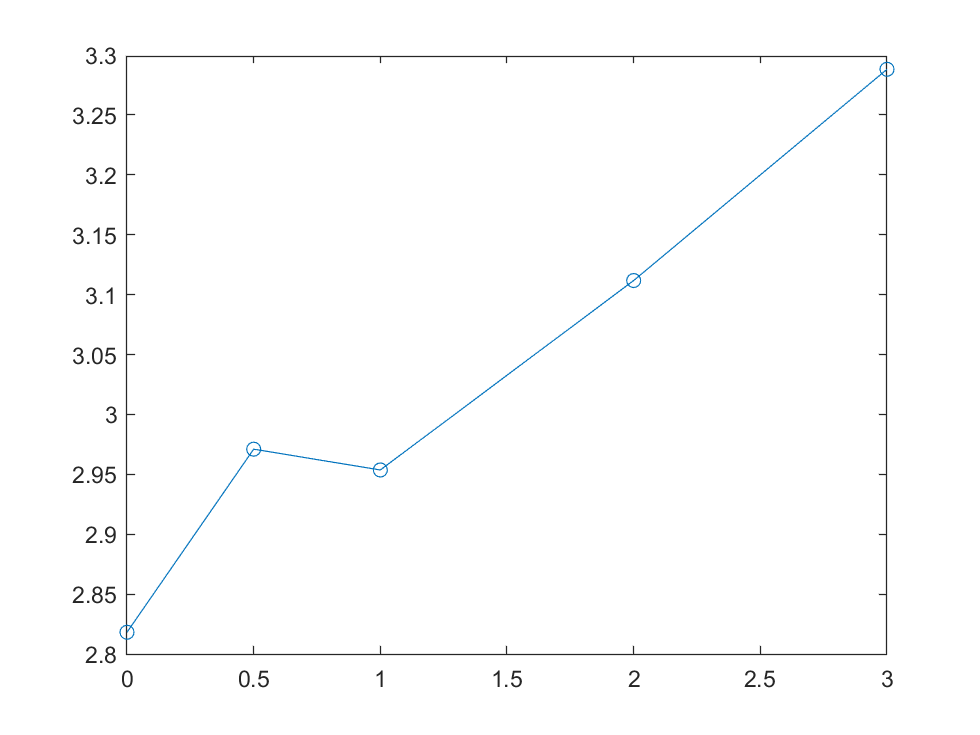


figure
plot(g_list, w_list, 'o-')

It seems that the omega increases from undamped to gamma=0.5, then decreases a little before raises further.

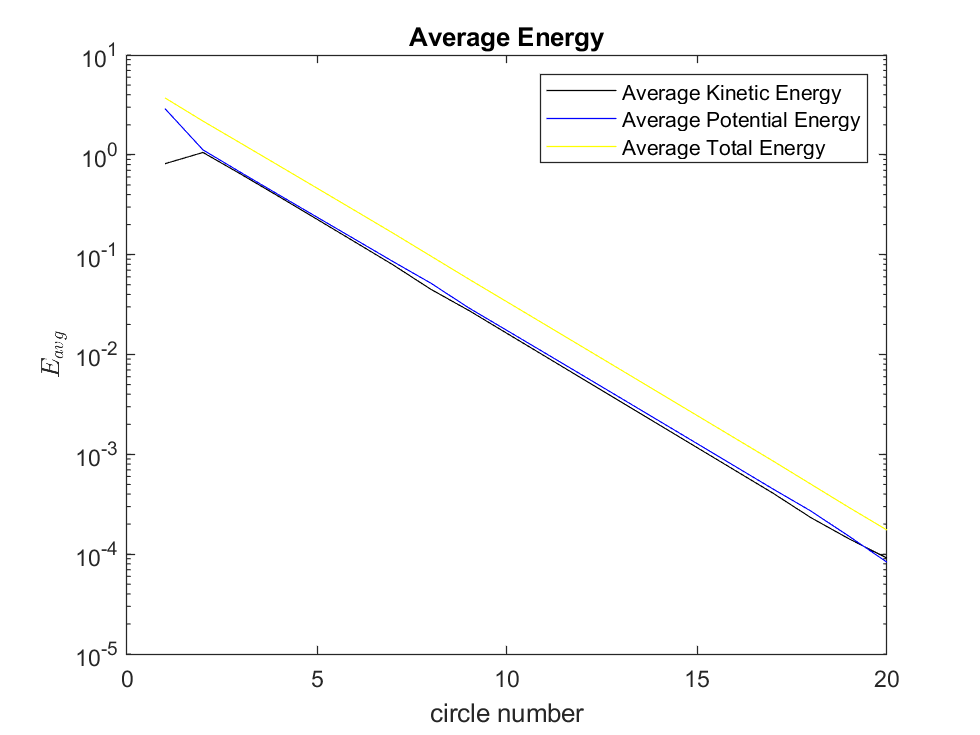

gamma = 0.5;
[t,w] = pendulum_damp(R,theta0,thetad0,gamma);
K = 0.5*R^2*w(:,2).^2;
U = 0.5*9*R^2*(sin(w(:,1))).^2;
ind = find(w(:,2).*circshift(w(:,2), [-1 0]) <= 0);
for i=1:length(ind)-1
    for j=1:ind(i+1)-ind(i)
        K1(j) = K(ind(i)+j-1);
        U1(j)  =U(ind(i)+j-1);
    end
    avgK(i) = mean(K1);
    avgV(i) = mean(U1);
    avgE(i) = avgK(i)+avgV(i);
    K1 = zeros;
    U1 = zeros;
    circle(i) = i;
end
semilogy(circle,avgK,'k-', circle,avgV,'b-', circle,avgE,'y-')
legend('Average Kinetic Energy','Average Potential Energy','Average Total Energy')
xlabel('circle number')
ylabel('$E_{avg}$','interpreter','latex')
title('Average Energy')

(c) One can see that the 3 energies decay exponentially. Its relative speed is uniform, but absolute speed is not uniform.

disp('    gamma    t_terminal')

    gamma    t_terminal


    4.0000    1.1176



    5.0000    1.6760



    6.0000    4.0385



    7.0000    5.7562



    8.0000    7.0741



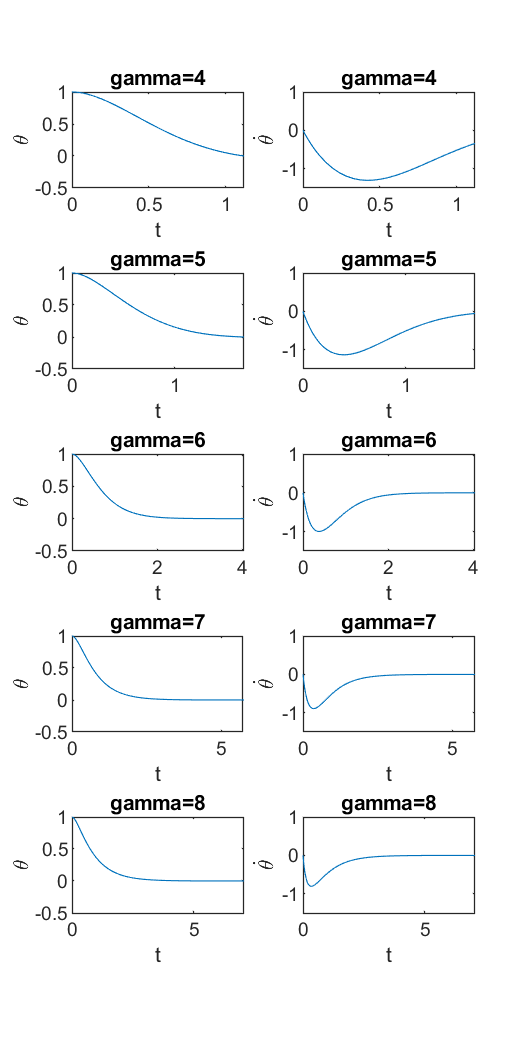

for gamma=4:8
    [t,w,t_terminal] = pendulum_damp_event(R,theta0,thetad0,gamma);
    disp([gamma, t_terminal])
    subplot(5,2,2*gamma-7)
    plot(t,w(:,1))
    title(['gamma=', num2str(gamma)])
    set(gcf,'Position',[0 0 200 600]);
    xlabel('t')
    ylabel('\theta')
    axis([0, t_terminal,-0.5,1])
    subplot(5,2,2*gamma-6)
    plot(t,w(:,2))
    title(['gamma=', num2str(gamma)])
    set(gcf,'Position',[0 0 300 600]);
    xlabel('t')
    ylabel('$\dot{\theta}$','interpreter','latex')
    axis([0, t_terminal,-1.5,1])
end

(d) As the damping coeffient increases, the equilibrium also increases. Because more friction means slower speed, and the distance is the same.

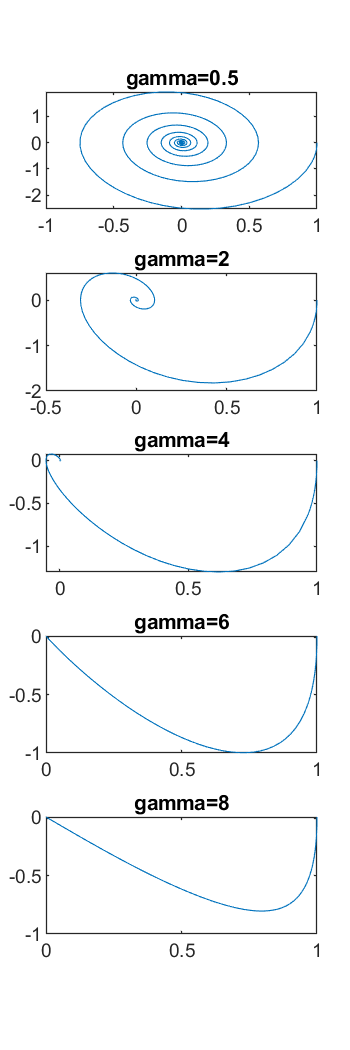

figure
hold on
i = 0;
for gamma=[0.5,2,4,6,8]
    i = i+1;
    [t,w] = pendulum_damp(R,theta0,thetad0,gamma);
    subplot(5,1,i)
    plot(w(:,1),w(:,2))
    title(['gamma=', num2str(gamma)])
    set(gcf,'Position',[0 0 200 600]);
end     

(e) The behavior of the path depends on gamma. There are 3 types: underdamped, overdamped, and critical point. For small gamma, the pendulum oscillates with exponential decay. The path is a screw line. For big gamma, the pendulum cannot oscillate. It goes to the equilibrium direction and no return.